%Find first n Hermite polynomials, H0=H(1),...
% Labelling actually starts with 0 but Matlab indexing
%  starts with 1 so our n is n+1 actually
clear
syms y

% y is the dimensionless position @y=sqrt(m*w/h)*x
% w is the angular frequency of the ground-state (lowest-energy) wavefunction
%    unit of w is rad/s

% m=9.11*e-31 kg                electron mass
% h=1.0546*e-34 Js              reduced Planck constant
% 1 eV=1.60217662*e-19 J
% J=kg*m^2/s^2
% erg=g*cm^2/s^2  = e-7 J
% k=2*pi/lambda rad/m
% w=2*pi*f rad/s

me=9.11*10^(-31);           %kg
h=1.0546*10^(-34);          %kg*m^2/s
eV=1.60217662*10^(-19);     %J=kg*m^2/s^2



n=20;
%k=mw/h
k=1;
Hermites=sym(zeros(1,n));
%A=sqrt(m*w/(pi*h))*(2^n*n!)^(-1/2)
A=(k/pi)^(-1/4)*(2.^(0:n-1).*factorial(0:n-1)).^(-1/2);

%Energy levels in terms of hw 
E=(1:n)-1/2; %since we have to start with 1 but actual labelling starts with 0
Elabels=["$$E_0 = \enspace$$";"$$E_1 = \enspace$$";"$$E_2 = \enspace$$";"$$E_3 = \enspace$$";"$$E_4 = \enspace$$";"$$E_5 = $$";"$$E_6 = $$";"$$E_7 = $$";"$$E_8 = $$";"$$E_9 = $$";"$$E_10 = $$";"$$E_11 = $$"];

Hermites(1)=1;
Hermites(2)=2*y;
%H_n(y)=2*y*H_(n-1)(y)-2*(n-2)*H_(n-2)(y)
%So knowing first 2 Hermite polynomials allows us to
%   calculate others
for ii=3:length(Hermites)
    Hermites(ii)=2*y*Hermites(ii-1)-2*(ii-2)*Hermites(ii-2);
end

%Y_n(y)=A(n)*Hermites(n)*exp(-y^2/2)
%epsilon=2*n+1 where epsilon is the dimensionless energy and
%   equals to E(n)/(hw/2)
f=A.*Hermites.*exp(-y^2/2);

P=f.^2;

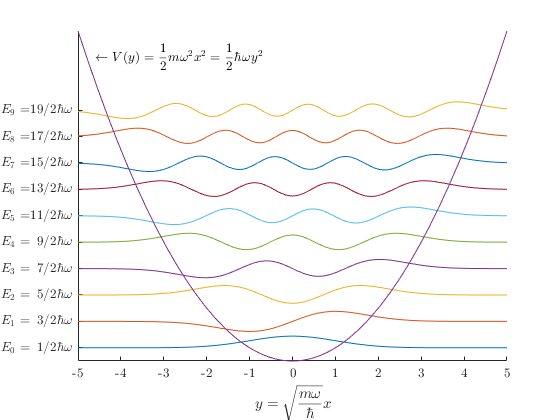

kk=10;  %First kk wavefunctions
scale=3; %In order the plot to looks good, change to see what it does

syms m w h

figure
hold on
fplot(f(1:kk)+E(1:kk)*scale)



%plot V, V=m*w^2*x^2/2=h*w*y^2/2
% since x and y axes normed to hw we plot y^2/2
fplot(scale*y^2/2)
xlabel('$$y=\sqrt{\frac{m\omega}{\hbar}}x$$','Interpreter','latex')
yticks(E(1:kk)*scale)
set(groot,'defaultAxesTickLabelInterpreter','latex'); %set tick label interpreter to latex
yticklabels(Elabels(1:kk)+string(sym(E(1:kk)'))+ '$$ \hbar \omega$$')
txt="$$\leftarrow V(y)=\frac{1}{2} m \omega^2 x^2 = \frac{1}{2} \hbar \omega y^2$$";
text(-4.6,scale*4.8^2/2,txt,'Interpreter','latex')
axis tight

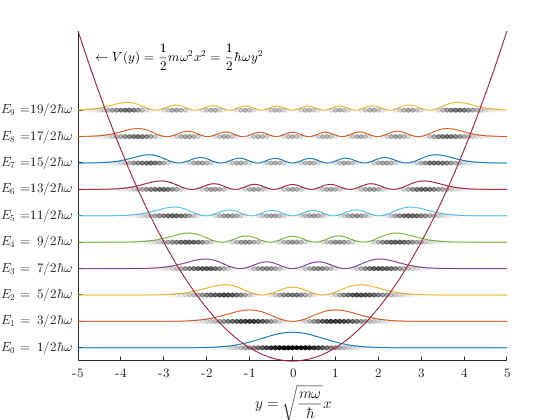

figure
hold on
fplot(P(1:kk)+E(1:kk)*scale)

for ii=1:kk
    %plot dots
    %their transparency is related to their probability
    xx=-5:.1:5;
    alphadata=subs(P(ii),y,xx);
    yy=scale*E(ii)*ones(1,length(xx));
    
    s=scatter(xx,yy);
    s.Marker='o';
    s.SizeData=10;
    s.AlphaData=alphadata;
    s.MarkerFaceAlpha='flat';
    s.MarkerFaceColor='k';
    s.MarkerEdgeColor='k';
    s.MarkerEdgeAlpha='flat';
end


fplot(scale*y^2/2)
xlabel('$$y=\sqrt{\frac{m\omega}{\hbar}}x$$','Interpreter','latex')
yticks(E(1:kk)*scale)
yticklabels(Elabels(1:kk)+string(sym(E(1:kk)'))+ '$$ \hbar \omega$$')
txt="$$\leftarrow V(y)=\frac{1}{2} m \omega^2 x^2 = \frac{1}{2} \hbar \omega y^2$$";
text(-4.6,scale*4.8^2/2,txt,'Interpreter','latex')
axis tight